# Train a Siamese Network to Compare Images

This example shows how to train a Siamese network to identify similar images of handwritten characters.

A Siamese network is a type of deep learning network that uses two or more identical subnetworks that have the same architecture and share the same parameters and weights. Siamese networks are typically used in tasks that involve finding the relationship between two comparable things. Some common applications for Siamese networks include facial recognition, signature verification [1], or paraphrase identification [2]. Siamese networks perform well in these tasks because their shared weights mean there are fewer parameters to learn during training and they can produce good results with a relatively small amount of training data.

Siamese networks are particularly useful in cases where there are large numbers of classes with small numbers of observations of each. In such cases, there is not enough data to train a deep convolutional neural network to classify images into these classes. Instead, the Siamese network can determine if two images are in the same class. 

This example use the Omniglot dataset [3] to train a Siamese network to compare images of handwritten characters [4]. The Omniglot dataset contains character sets for 50 alphabets, divided into 30 used for training and 20 for testing. Each alphabet contains a number of characters from 14 for Ojibwe (Canadia Aboriginal Sullabics) to 55 for Tifinagh. Finally, each character has 20 handwritten observations. This example trains a network to identify whether two handwritten observations are different instances of the same character.

You can also use Siamese networks to identify similar images using dimensionality reduction. For an example, see [Train a Siamese Network for Dimensionality Reduction](docid:nnet_ug#mw_724e1879-4f23-49ad-aab5-8ce7a801e20a).

## **Load and Preprocess Training Data**

Download and extract the [Omniglot](https://github.com/brendenlake/omniglot) training dataset.

url = "https://github.com/brendenlake/omniglot/raw/master/python/images_background.zip";
downloadFolder = tempdir;
filename = fullfile(downloadFolder,"images_background.zip");

dataFolderTrain = fullfile(downloadFolder,'images_background');
if ~exist(dataFolderTrain,"dir")
    disp("Downloading Omniglot training data (4.5 MB)...")
    websave(filename,url);
    unzip(filename,downloadFolder);
end
disp("Training data downloaded.")

Training data downloaded.


Load the training data as a image datastore using the `imageDatastore` function. Specify the labels manually by extracting the labels from the file names and setting the `Labels` property.

imdsTrain = imageDatastore(dataFolderTrain, ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');

files = imdsTrain.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTrain.Labels = categorical(labels);

The Omniglot training dataset consists of black and white handwritten characters from 30 alphabets, with 20 observations of each character. The images are of size 105-by-105-by-1, and the values of each pixel are between `0` and `1`. 

Display a random selection of the images.

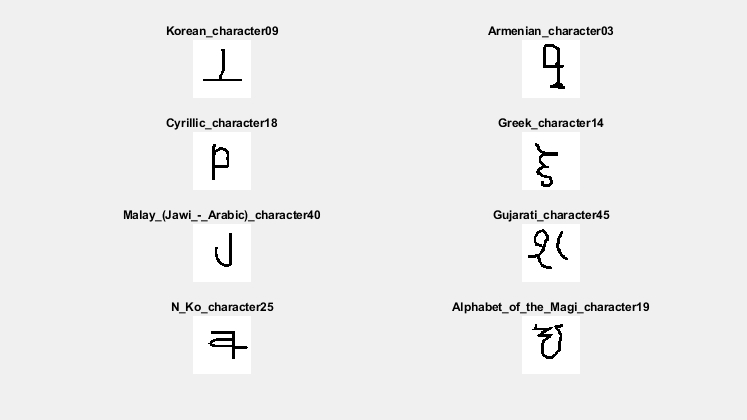

idxs = randperm(numel(imdsTrain.Files),8);

for i = 1:numel(idxs)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,idxs(i)))
    title(imdsTrain.Labels(idxs(i)), "Interpreter","none");
end

## **Create Pairs of Similar and Dissimilar Images**

To train the network, the data must be grouped into pairs of images that are either similar or dissimilar. Here, similar images are different handwritten instances of the same character, which have the same label, while dissimilar images of different characters have different labels. The function `getSiameseBatch` (defined in the Supporting Functions section of this example) creates randomized pairs of similar or dissimilar images, `pairImage1 `and `pairImage2`. The function also returns the label `pairLabel`, which identifies if the pair of images is similar or dissimilar to each other. Similar pairs of images have `pairLabel = 1`, while dissimilar pairs have `pairLabel = 0`.

As an example, create a small representative set of five pairs of images

batchSize = 10;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);

Display the generated pairs of images. 

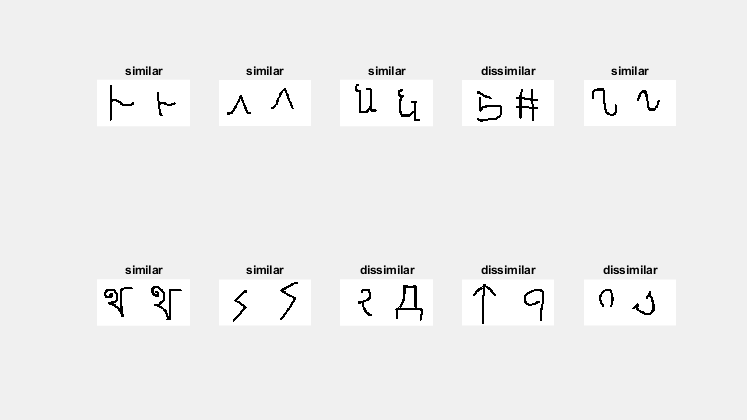

for i = 1:batchSize    
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(2,5,i)   
    imshow([pairImage1(:,:,:,i) pairImage2(:,:,:,i)]);
    title(s)
end

In this example, a new batch of 180 paired images is created for each iteration of the training loop. This ensures that the network is trained on a large number of random pairs of images with approximately equal proportions of similar and dissimilar pairs.

## **Define Network Architecture**

The Siamese network architecture is illustrated in the following diagram.

 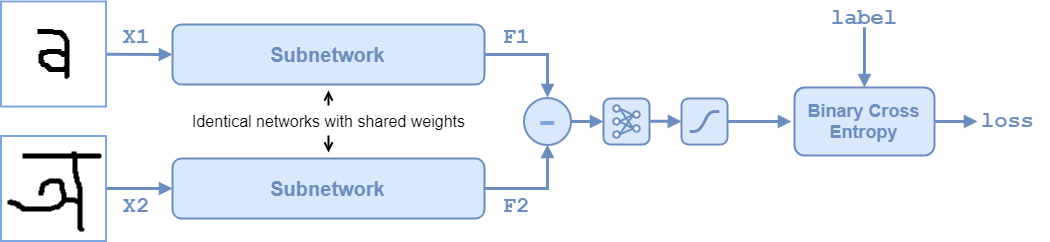

To compare two images, each image is passed through one of two identical subnetworks that share weights. The subnetworks convert each 105-by-105-by-1 image to a 4096-dimensional feature vector. Images of the same class have similar 4096-dimensional representations.. The output feature vectors from each subnetwork are combined through subtraction and the result is passed through a `fullyconnect` operation with a single output. A `sigmoid` operation converts this value to a probability between `0` and `1`, indicating the network's prediction of whether the images are similar or dissimilar. The binary cross-entropy loss between the network prediction and the true label is used to update the network during training.

In this example, the two identical subnetworks are defined as a `dlnetwork` object. The final `fullyconnect` and `sigmoid` operations are performed as functional operations on the subnetwork outputs. 

Create the subnetwork as a series of layers that accepts 105-by-105-by-1 images and outputs a feature vector of size 4096.

For the `convolution2dLayer` objects, use the narrow normal distribution to initialize the weights and bias.

For the `maxPooling2dLayer` objects, set the stride to `2`.

For the final `fullyConnectedLayer` object, specify an output size of 4096 and use the narrow normal distribution to initialize the weights and bias.

layers = [
    imageInputLayer([105 105 1],'Name','input1','Normalization','none')
    convolution2dLayer(10,64,'Name','conv1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu1')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool1')
    convolution2dLayer(7,128,'Name','conv2','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu2')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool2')
    convolution2dLayer(4,128,'Name','conv3','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu3')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool3')
    convolution2dLayer(5,256,'Name','conv4','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu4')
    fullyConnectedLayer(4096,'Name','fc1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')];

lgraph = layerGraph(layers);

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a `dlnetwork` object.

dlnet = dlnetwork(lgraph);

Create the weights for the final `fullyconnect` operation. Initialize the weights by sampling a random selection from a narrow normal distribution with standard deviation of 0.01.

fcWeights = dlarray(0.01*randn(1,4096));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

To use the network, create the function `forwardSiamese` (defined in the Supporting Functions section of this example) that defines how the two subnetworks and the subtraction, `fullyconnect,` and `sigmoid` operations are combined. The function `forwardSiamese` accepts the network, the structure containing the parameters for the `fullyconnect` operation, and two training images. The `forwardSiamese` function outputs a prediction about the similarity of the two images. 

## Define Model Gradients Function

Create the function `modelGradients` (defined in the Supporting Functions section of this example). The `modelGradients` function takes the Siamese subnetwork `dlnet`, the parameter structure for the `fullyconnect` operation, and a mini-batch of input data `X1` and `X2` with their labels `pairLabels`.  The function returns the loss values and the gradients of the loss with respect to the learnable parameters of the network.

The objective of the Siamese network is to discriminate between the two inputs `X1` and `X2`. The output of the network is a probability between `0` and `1`, where a value closer to `0` indicates a prediction that the images are dissimilar, and a value closer to `1` that the images are similar. The loss is given by the binary cross-entropy between the predicted score and the true label value: 


$$\mathrm{loss}=-\mathrm{tlog}\left(y\right)-\left(1-t\right)\mathrm{log}\left(1-y\right),$$


where the true label $t$ can be 0 or 1 and $y$ is the predicted label.

## **Specify Training Options**

Specify the options to use during training. Train for 10000 iterations.

numIterations = 10000;
miniBatchSize = 180;

Specify the options for ADAM optimization:

- Set the learning rate to `0.00006`.

- Initialize the trailing average gradient and trailing average gradient-square decay rates with `[]` for both `dlnet` and `fcParams`.

- Set the gradient decay factor to `0.9` and the squared gradient decay factor to `0.99`.

learningRate = 6e-5;
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];
gradDecay = 0.9;
gradDecaySq = 0.99;

Train on a GPU, if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher. To automatically detect if you have a GPU available and place the relevant data on the GPU, set the value of `executionEnvironment` to `"auto"`. If you don't have a GPU, or don't want to use one for training, set the value of `executionEnvironment` to `"cpu"`. To ensure you use a GPU for training, set the value of `executionEnvironment` to `"gpu"`. 

executionEnvironment = "auto";

To monitor the training progress, you can plot the training loss after each iteration. Create the variable `plots` that contains `"training-progress"`.  If you don't want to plot the training progress, set this value to `"none"`.

plots = "training-progress";

Initialize the plot parameters for the training loss progress plot.

plotRatio = 16/9;

if plots == "training-progress"
    trainingPlot = figure;
    trainingPlot.Position(3) = plotRatio*trainingPlot.Position(4);
    trainingPlot.Visible = 'on';
    
    trainingPlotAxes = gca;
    
    lineLossTrain = animatedline(trainingPlotAxes);
    xlabel(trainingPlotAxes,"Iteration")
    ylabel(trainingPlotAxes,"Loss")
    title(trainingPlotAxes,"Loss During Training")
end

## Train Model

Train the model using a custom training loop. Loop over the training data and update the network parameters at each iteration. 

For each iteration:

- Extract a batch of image pairs and labels using the `getSiameseBatch` function defined in the section Create Batches of Image Pairs.

- Convert the data to `dlarray` objects with underlying type `single` and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch) for the image data and `'CB'` (channel, batch) for the labels.

- For GPU training, convert the data to `gpuArray` objects.

- Evaluate the model gradients using `dlfeval` and the `modelGradients` function.

- Update the network parameters using the `adamupdate` function.

% Loop over mini-batches.
for iteration = 1:numIterations
    
    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data
    dlX1 = dlarray(single(X1),'SSCB');
    dlX2 = dlarray(single(X2),'SSCB');
    
    % If training on a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        dlX1 = gpuArray(dlX1);
        dlX2 = gpuArray(dlX2);
    end  
    
    % Evaluate the model gradients and the generator state using
    % dlfeval and the modelGradients function listed at the end of the
    % example.
    [gradientsSubnet, gradientsParams,loss] = dlfeval(@modelGradients,dlnet,fcParams,dlX1,dlX2,pairLabels);
    lossValue = double(gather(extractdata(loss)));
    
    % Update the Siamese subnetwork parameters.
    [dlnet,trailingAvgSubnet,trailingAvgSqSubnet] = ...
        adamupdate(dlnet,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);
    
    % Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = ...
        adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);
      
    % Update the training loss progress plot.
    if plots == "training-progress"
        addpoints(lineLossTrain,iteration,lossValue);
    end
    drawnow;
end

## Evaluate the Accuracy of the Network

Download and extract the [Omniglot](https://github.com/brendenlake/omniglot) test dataset.

url = 'https://github.com/brendenlake/omniglot/raw/master/python/images_evaluation.zip';
downloadFolder = tempdir;
filename = fullfile(downloadFolder,'images_evaluation.zip');

dataFolderTest = fullfile(downloadFolder,'images_evaluation');
if ~exist(dataFolderTest,'dir')
    disp('Downloading Omniglot test data (3.2 MB)...')
    websave(filename,url);
    unzip(filename,downloadFolder);
end

disp("Test data downloaded.")

Test data downloaded.


Load the test data as a image datastore using the `imageDatastore` function. Specify the labels manually by extracting the labels from the file names and setting the `Labels` property.

imdsTest = imageDatastore(dataFolderTest, ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');    

files = imdsTest.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTest.Labels = categorical(labels);

The test dataset contains 20 alphabets that are different to those that the network was trained on. In total, there 659 different classes in the test dataset.

numClasses = numel(unique(imdsTest.Labels))

numClasses = 659

To calculate the accuracy of the network, create a set of five random mini-batches of test pairs. Use the `predictSiamese` function (defined in the Supporting Functions section of this example) to evaluate the network predictions and calculate the average accuracy over the mini-batches.

accuracy = zeros(1,5);
accuracyBatchSize = 150;

for i = 1:5
    
    % Extract mini-batch of image pairs and pair labels
    [XAcc1,XAcc2,pairLabelsAcc] = getSiameseBatch(imdsTest,accuracyBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data.
    dlXAcc1 = dlarray(single(XAcc1),'SSCB');
    dlXAcc2 = dlarray(single(XAcc2),'SSCB');
    
    % If using a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
       dlXAcc1 = gpuArray(dlXAcc1);
       dlXAcc2 = gpuArray(dlXAcc2);
    end    
    
    % Evaluate predictions using trained network
    dlY = predictSiamese(dlnet,fcParams,dlXAcc1,dlXAcc2);
   
    % Convert predictions to binary 0 or 1
    Y = gather(extractdata(dlY));
    Y = round(Y);
    
    % Compute average accuracye for the minibatch
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

% Compute accuracy over all minibatches
averageAccuracy = mean(accuracy)*100

averageAccuracy = 66.8000

## **Display a Test Set of Images with Predictions**

To visually check if the network correctly identifies similar and dissimilar pairs, create a small batch of image pairs to test. Use the predictSiamese function to get the prediction for each test pair. Display the pair of images with the prediction, the probability score, and a label indicating whether the prediction was correct or incorrect.

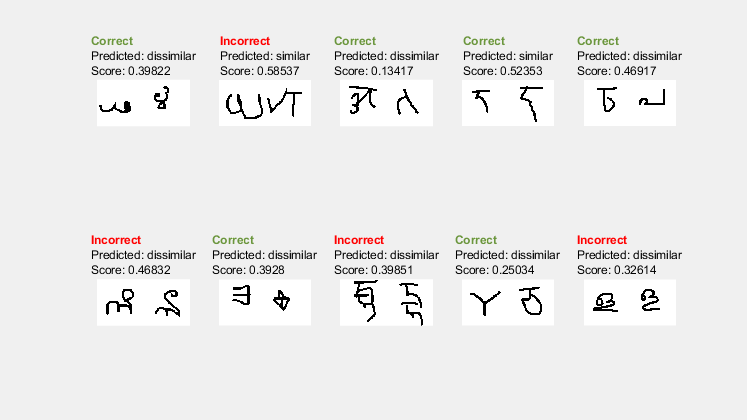

testBatchSize = 10;

[XTest1,XTest2,pairLabelsTest] = getSiameseBatch(imdsTest,testBatchSize);
    
% Convert test batch of data to dlarray. Specify the dimension labels
% 'SSCB' (spatial, spatial, channel, batch) for image data and 'CB' 
% (channel, batch) for labels
dlXTest1 = dlarray(single(XTest1),'SSCB');
dlXTest2 = dlarray(single(XTest2),'SSCB');

% If using a GPU, then convert data to gpuArray
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
   dlXTest1 = gpuArray(dlXTest1);
   dlXTest2 = gpuArray(dlXTest2);
end

% Calculate the predicted probability
dlYScore = predictSiamese(dlnet,fcParams,dlXTest1,dlXTest2);
YScore = gather(extractdata(dlYScore));

% Convert predictions to binary 0 or 1
YPred = round(YScore);    

% Extract data to plot
XTest1 = extractdata(dlXTest1);
XTest2 = extractdata(dlXTest2);

% Plot images with predicted label and predicted score
testingPlot = figure;
testingPlot.Position(3) = plotRatio*testingPlot.Position(4);
testingPlot.Visible = 'on';
    
for i = 1:numel(pairLabelsTest)
     
    if YPred(i) == 1
        predLabel = "similar";
    else
        predLabel = "dissimilar" ;
    end
    
    if pairLabelsTest(i) == YPred(i)
        testStr = "\bf\color{darkgreen}Correct\rm\newline";
        
    else
        testStr = "\bf\color{red}Incorrect\rm\newline";
    end
    
    subplot(2,5,i)        
    imshow([XTest1(:,:,:,i) XTest2(:,:,:,i)]);        
    
    title(testStr + "\color{black}Predicted: " + predLabel + "\newlineScore: " + YScore(i)); 
end

The network is able to compare the test images to determine their similarity, even though none of these images were in the training dataset. 

## Supporting Functions

### Model Functions for Training and Prediction

The function `forwardSiamese` is used during network training. The function defines how the subnetworks and the `fullyconnect` and `sigmoid` operations combine to form the complete Siamese network. forwardSiamese accepts the network structure and two training images and outputs a prediction about the similarity of the two images. Within this example, the function `forwardSiamese` is introduced in the section Define Network Architecture.

function Y = forwardSiamese(dlnet,fcParams,dlX1,dlX2)
% forwardSiamese accepts the network and pair of training images, and returns a
% prediction of the probability of the pair being similar (closer to 1) or 
% dissimilar (closer to 0). Use forwardSiamese during training.

    % Pass the first image through the twin subnetwork
    F1 = forward(dlnet,dlX1);
    F1 = sigmoid(F1);
    
    % Pass the second image through the twin subnetwork
    F2 = forward(dlnet,dlX2);
    F2 = sigmoid(F2);
    
    % Subtract the feature vectors
    Y = abs(F1 - F2);
    
    % Pass the result through a fullyconnect operation
    Y = fullyconnect(Y,fcParams.FcWeights,fcParams.FcBias);
    
    % Convert to probability between 0 and 1.
    Y = sigmoid(Y);
end

The function `predictSiamese` uses the trained network to make predictions about the similarity of two images. The function is similar to the function `forwardSiamese`, defined previously. However, `predictSiamese` uses the `predict` function with the network instead of the `forward` function, because some deep learning layers behave differently during training and prediction. Within this example, the function `predictSiamese` is introduced in the section Evaluate the Accuracy of the Network.

function Y = predictSiamese(dlnet,fcParams,dlX1,dlX2)
% predictSiamese accepts the network and pair of images, and returns a
% prediction of the probability of the pair being similar (closer to 1)
% or dissimilar (closer to 0). Use predictSiamese during prediction.

    % Pass the first image through the twin subnetwork
    F1 = predict(dlnet,dlX1);
    F1 = sigmoid(F1);
    
    % Pass the second image through the twin subnetwork
    F2 = predict(dlnet,dlX2);
    F2 = sigmoid(F2);
    
    % Subtract the feature vectors
    Y = abs(F1 - F2);
    
    % Pass the result through a fullyconnect operation
    Y = fullyconnect(Y,fcParams.FcWeights,fcParams.FcBias);
    
    % Convert to probability between 0 and 1.
    Y = sigmoid(Y);
end

### Model Gradients Function

The function `modelGradients` takes the Siamese `dlnetwork` object `net`, a pair of mini-batch input data `X1` and `X2`, and the label indicating whether they are similar or dissimilar. The function returns the gradients of the loss with respect to the learnable parameters in the network and the binary cross-entropy loss between the prediction and the ground truth. Within this example, the function `modelGradients` is introduced in the section Define Model Gradients Function.

function [gradientsSubnet,gradientsParams,loss] = modelGradients(dlnet,fcParams,dlX1,dlX2,pairLabels)
% The modelGradients function calculates the binary cross-entropy loss between the
% paired images and returns the loss and the gradients of the loss with respect to
% the network learnable parameters

    % Pass the image pair through the network 
    Y = forwardSiamese(dlnet,fcParams,dlX1,dlX2);
    
    % Calculate binary cross-entropy loss
    loss = binarycrossentropy(Y,pairLabels);
       
    % Calculate gradients of the loss with respect to the network learnable
    % parameters
    [gradientsSubnet,gradientsParams] = dlgradient(loss,dlnet.Learnables,fcParams);
end

function loss = binarycrossentropy(Y,pairLabels)
    % binarycrossentropy accepts the network's prediction, Y, the true
    % label, pairLabels, and returns the binary cross-entropy loss value.
    
    % Get the precision of the prediction to prevent errors due to floating
    % point precision    
    y = extractdata(Y);
    if(isa(y,'gpuArray'))
        precision = classUnderlying(y);
    else
        precision = class(y);
    end
      
    % Convert values less than floating point precision to eps.
    Y(Y < eps(precision)) = eps(precision);
    %convert values between 1-eps and 1 to 1-eps.
    Y(Y > 1 - eps(precision)) = 1 - eps(precision);
    
    % Calculate binary cross-entropy loss for each pair
    loss = -pairLabels.*log(Y) - (1 - pairLabels).*log(1 - Y);
    
    % Sum over all pairs in minibatch and normalize.
    loss = sum(loss)/numel(pairLabels);
end

### Create Batches of Image Pairs

The following functions create randomized pairs of images that are similar or dissimilar, based on their labels. Within this example, the function `getSiameseBatch` is introduced in the section Create Pairs of Similar and Dissimilar Images.

function [X1,X2,pairLabels] = getSiameseBatch(imds,miniBatchSize)
% getSiameseBatch returns a randomly selected batch or paired images. On
% average, this function produces a balanced set of similar and dissimilar
% pairs.

    pairLabels = zeros(1,miniBatchSize);
    imgSize = size(readimage(imds,1));
    X1 = zeros([imgSize 1 miniBatchSize]);
    X2 = zeros([imgSize 1 miniBatchSize]);

    for i = 1:miniBatchSize
        choice = rand(1);
        if choice < 0.5
            [pairIdx1,pairIdx2,pairLabels(i)] = getSimilarPair(imds.Labels);
        else
            [pairIdx1,pairIdx2,pairLabels(i)] = getDissimilarPair(imds.Labels);
        end
        X1(:,:,:,i) = imds.readimage(pairIdx1);
        X2(:,:,:,i) = imds.readimage(pairIdx2);
    end
end

function [pairIdx1,pairIdx2,pairLabel] = getSimilarPair(classLabel)
% getSimilarSiamesePair returns a random pair of indices for images
% that are in the same class and the similar pair label = 1.

    % Find all unique classes.
    classes = unique(classLabel);
    
    % Choose a class randomly which will be used to get a similar pair.
    classChoice = randi(numel(classes));
    
    % Find the indices of all the observations from the chosen class.
    idxs = find(classLabel==classes(classChoice));
    
    % Randomly choose two different images from the chosen class.
    pairIdxChoice = randperm(numel(idxs),2);
    pairIdx1 = idxs(pairIdxChoice(1));
    pairIdx2 = idxs(pairIdxChoice(2));
    pairLabel = 1;
end

function  [pairIdx1,pairIdx2,label] = getDissimilarPair(classLabel)
% getDissimilarSiamesePair returns a random pair of indices for images
% that are in different classes and the dissimilar pair label = 0.

    % Find all unique classes.
    classes = unique(classLabel);
    
    % Choose two different classes randomly which will be used to get a dissimilar pair.
    classesChoice = randperm(numel(classes),2);
    
    % Find the indices of all the observations from the first and second classes.
    idxs1 = find(classLabel==classes(classesChoice(1)));
    idxs2 = find(classLabel==classes(classesChoice(2)));
    
    % Randomly choose one image from each class.
    pairIdx1Choice = randi(numel(idxs1));
    pairIdx2Choice = randi(numel(idxs2));
    pairIdx1 = idxs1(pairIdx1Choice);
    pairIdx2 = idxs2(pairIdx2Choice);
    label = 0;
end

## **References**

[1] Bromley, J., I. Guyon, Y. LeCunn, E. Säckinger, and R. Shah. "*Signature Verification using a "Siamese" Time Delay Neural Network.*" In Proceedings of the 6th International Conference on Neural Information Processing Systems (NIPS 1993), 1994, pp737-744. Available at [Signature Verification using a "Siamese" Time Delay Neural Network](https://papers.nips.cc/paper/769-signature-verification-using-a-siamese-time-delay-neural-network.pdf) on the NIPS Proceedings website. 

[2] Wenpeg, Y., and H Schütze. "*Convolutional Neural Network for Paraphrase Identification.*" In Proceedings of 2015 Conference of the North American Chapter of the ACL, 2015, pp901-911. Available at [Convolutional Neural Network for Paraphrase Identification](https://www.aclweb.org/anthology/N15-1091) on the ACL Anthology website

[3] Lake, B. M., Salakhutdinov, R., and Tenenbaum, J. B. "*Human-level concept learning through probabilistic program induction.*" Science, 350(6266), (2015) pp1332-1338.

[4] Koch, G., Zemel, R., and Salakhutdinov, R. (2015). "*Siamese neural networks for one-shot image recognition*". In Proceedings of the 32nd International Conference on Machine Learning, 37 (2015). Available at [Siamese Neural Networks for One-shot Image Recognition](https://8109f4a4-a-62cb3a1a-s-sites.googlegroups.com/site/deeplearning2015/37.pdf?attachauth=ANoY7crZQv10TQnwz42cHSNBlNvtZChn-84xsEc-ChrL4sdYDOlfLFLexHRNnvrjm6B-HeXsanRvuVT6a1pmVD7ujxLF65e30KuT3drP8azPUuCOwxVEITyVKW9dyP5UqqPRvDde3RIbVAuGiYIiC5K4BEKfmEYMkPVxD2yj_U-QmoLliupUVmx65b_hwexNKxi5fVricrVNHgNxrEIv5n6RrKDn2uWuxg%3D%3D&attredirects=0) on the ICML'15 website. 

*Copyright 2019 The MathWorks, Inc.*